# **Lab 6. Static system identification using neural networks**

Through this lab we will learn the basics of the Deep Learning Toolbox to train a neural network in order to approximate a static system.

## 1. Generating the static system

Before creating and training our neural network, we need to define the static system we want to approximate.

### 1.1. Extracting data

We are interested in approximating this function in the interval $\left\lbrack 0,4\right\rbrack$, so we compute the outputs of the function in this interval.

% Interval
x = 0:0.04:4;

% Outputs
y0 = 4.3*(exp(-x)-4*exp(-2*x)+3*exp(-3*x));

As we can see this is a non convex function expressed as the sum of three exponential functions.

### 1.2. Adding some noise

Then we declare a noise vector since measurements are always affected by noise.

% Standard deviation of noise
sigma = 0.2;

% Noise vector
n = sigma.*randn(size(y0));

Since the outputs of the function are relatively small, we introduced a small amount of noise otherwise we would have completely lost the information about the outputs of the function. In particulare, we scaled noise using its standard deviation.

We can now sum the noise to the output vector.

% Noisy outputs
y = y0 + n;

### 1.3. Plotting data

Let's see how noise affected the outputs of the function.

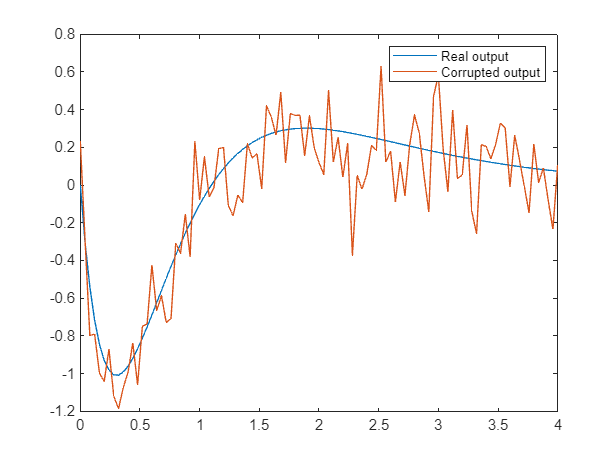

% Comparison
figure(1), plot(x,y0,x,y),
legend("Real output", "Corrupted output")

As we can see there is an important difference in the behaviour of the output.

## 2. Using the neural network

We will use a neural network in order to try to reconstruct the true output of the function starting from the inputs and the noisy output.

### 2.1. Defining the neural network

In order to define a neural network, we need to use the command `feedforwardnet`. This command will create a neural network with a classic Multi-Layer Perceptron (MLP) architecture. We need to specify the number of neurons for each of the considered hidden layers.

% Neural network
net = feedforwardnet([4,2]);

### 2.2. Visualizing the neural network

We can visualize the structure of the neural network we just created using the command `view`.

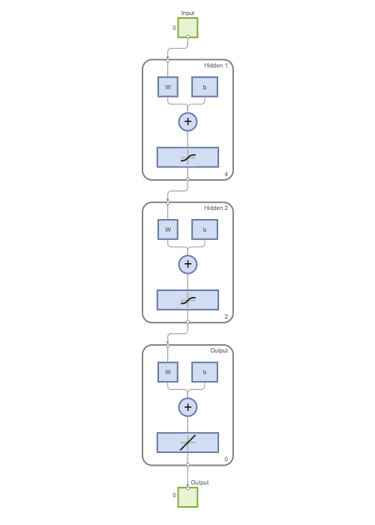

% Visualizing neural network
view(net)

As we can see there are two hidden layers with sigmoidal activation functions and one output layer with a linear activation function.

### 2.3. Properties of the neural networks

We can easily assess the information about the activation functions using the property `transferFcn`.

% Hidden layer activation function
net.layers{1}.transferFcn

ans = 'tansig'


% Output layer activation function
net.layers{2}.transferFcn

ans = 'tansig'

Since we will train our neural network, we need to specify the maximum epochs for training.

% Maximum number of epochs
net.trainParam.epochs = 200;

### 2.4. Training the neural network

Now we train our neural network using the backpropagation algorithm. MATLAB will automatically split the dataset in three parts.

- Training set: data used to determine the optimal weights of the neural network with the training algorithm.

- Validation set: data used to evauate the training process of the neural network through the computation of the Mean Squared Error (MSE) for each epoch. If this index increases, the training process will stop to avoid the overtraining phenomena.

- Test set: data used for similar purposes of the validation set, but the training does not stop.

We define a new neural network that will have the optimal parameters computed by the training algorithm. In this way we can preserve the original parameters of the network without overwriting them.

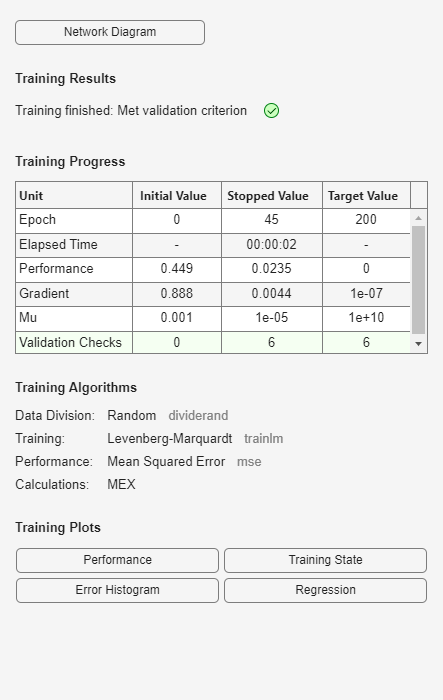

% Training the neural network
[trainedNet,tr] = train(net,x,y);

The training process also gave us back the record of the training, which is a structure containing useful information about the process. For example we see that the training process stopped after only 31 epochs. Also, we can have a rough measurement of the quality of the training process by looking at the gradient. Our stopped value is slightly higher than the target value.

### 2.5. Performance indexes

Starting from this structure we can plot the performance indexes, i.e. the MSE, for each of the three sets.

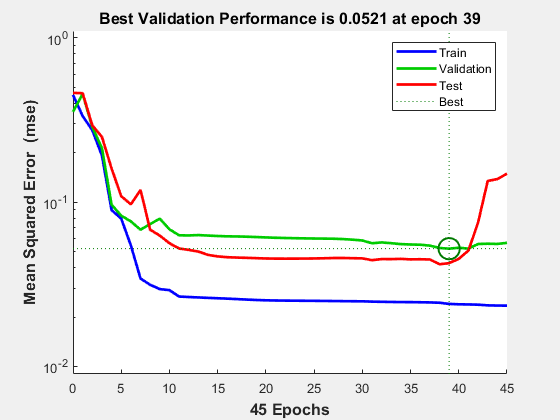

% Plotting records
figure(2), plotperform(tr)

As expected, the MSE computed over the training set always decreases. The MSE computed over the validation set initially decreases and then, after reaching its minimum, it starts to increase again. So, if we want to prevent overtraining, we need to stop at the epoch in which the MSE computed over the validation set is minimum. Otherwise, the performance could deteriorate.

Since the weights of the neural network are initialized differently each time, if we perform again the training we would find different results. Let us keep in mind that the optimization algorithm is deterministic: if we start from the same weights, we get the same results. 

### 2.6. Computing predictions

In order to evaluate how well the neural network output is, we need to compute it.

% Neural network output
ynet = sim(trainedNet,x);

Now we can plot the difference between the real output, the corrupted output and the predicted output.

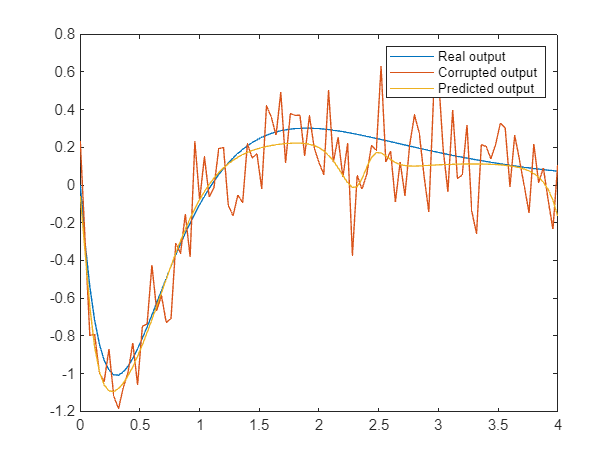

% Comparison between outputs
figure(3), plot(x,y0,x,y,x,ynet),
legend("Real output","Corrupted output","Predicted output");

As we can see the neural network did quite a good job, if we consider the magnitude of noise!